red = 1.1;
green = 1.2;
blue = 1.3;
yellow = 1.4;

CameraCalibration;


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1333.7707 +/- 2.9103     1332.8945 +/- 2.8864  ]
Principal point (pixels):[  767.0637 +/- 1.2716      591.1662 +/- 1.1437  ]
Radial distortion:       [    0.0703 +/- 0.0037       -0.1904 +/- 0.0077  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0608 +/- 0.0034        0.0335 +/- 0.0033        1.5415 +/- 0.0003  ]
                         [   -0.1415 +/- 0.0031       -0.3623 +/- 0.0030       -0.7940 +/- 0.0004  ]
                         [   -0.3486 +/- 0.0015        0.3479 +/- 0.0015       -0.0041 +/- 0.0004  ]
                         [    0.0191 +/- 0.0017        0.5804 +/- 0.0018        0.0162 +/- 0.0004  ]
                         [   -0.2515 +/- 0.0050       -0.2794 +/- 0.0052        1.5264 +/- 0.0009  ]
                         [   -0.4045 +/- 0.0021        0.4554 +/- 0.0021        1.5155 +/- 0.0005  ]
 

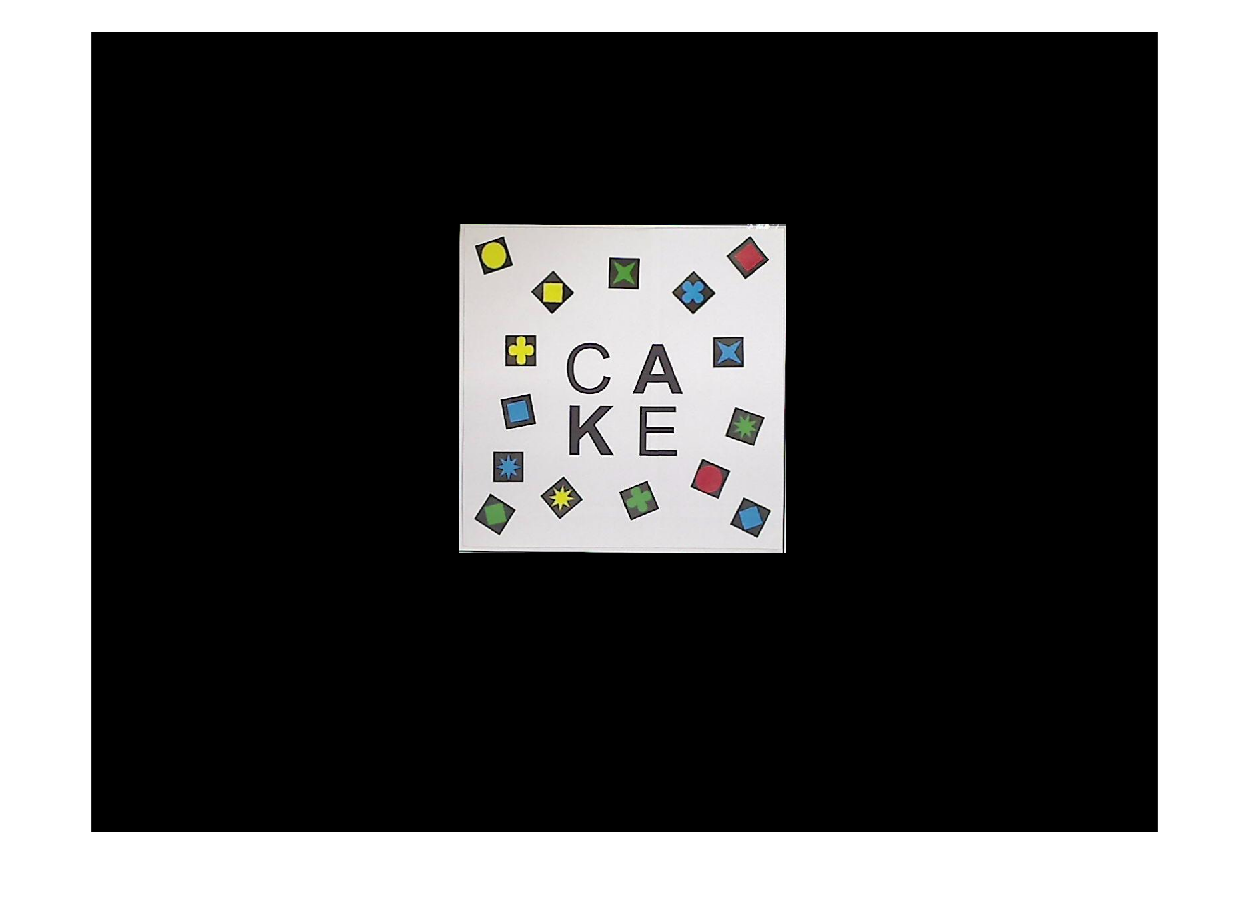


%% Identify shapes and colour of the pattern
table_Img = imread('Proper_Pics\PrintedPics\cake.jpg');
table_Img = undistortImage(table_Img, cameraParams);
table_Img = segmentSection(table_Img, 552, 1043, 288, 782);
figure; imshow(table_Img);

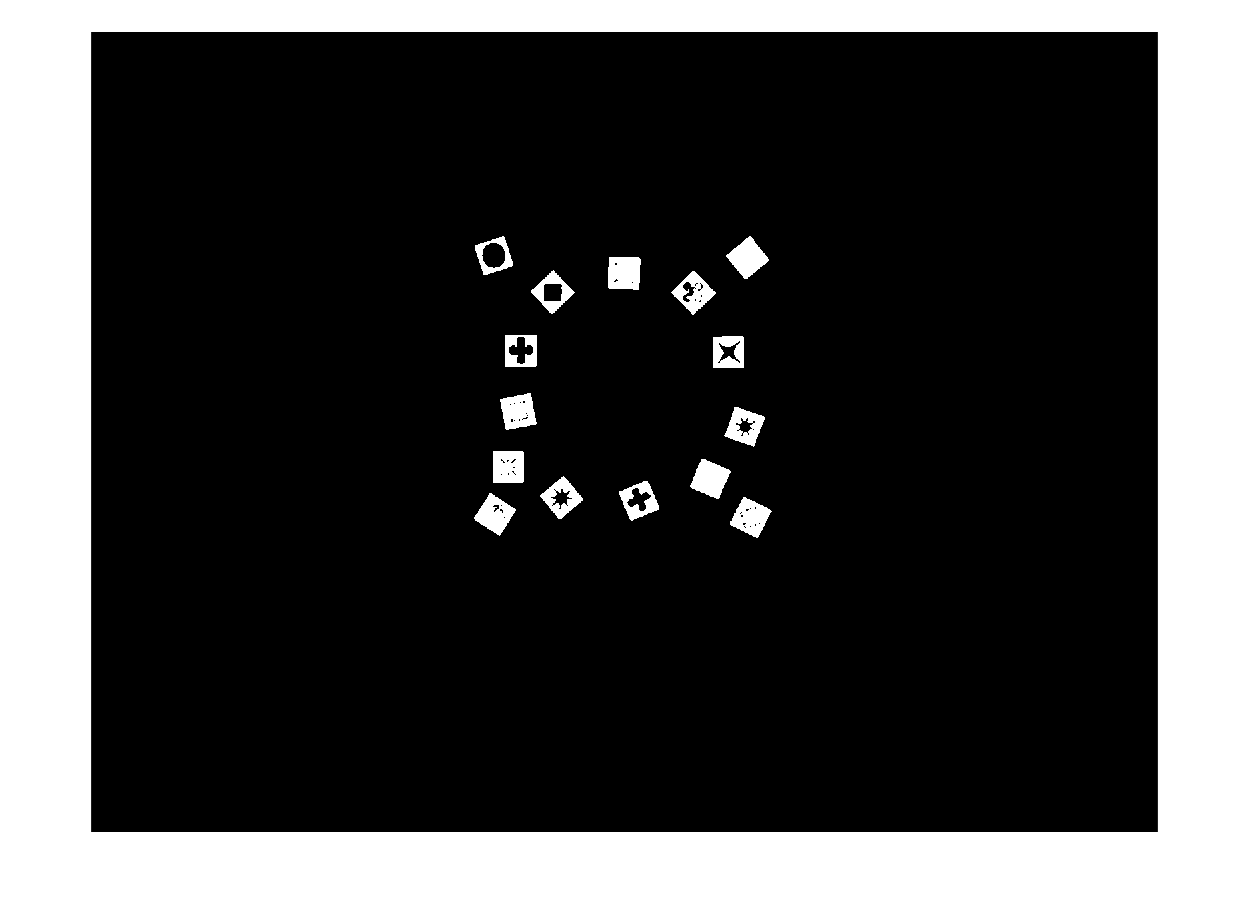


table_ImgBW = ~im2bw(table_Img);
table_ImgBW = segmentSection(table_ImgBW, 552, 1043, 288, 782);
table_ImgBW = removeLettersAndNumbers(table_ImgBW);
table_ImgBW = bwareaopen(table_ImgBW,100);
se = strel('square',10);
table_ImgBW = bwmorph(table_ImgBW, 'thicken');
table_ImgBW = bwmorph(table_ImgBW, 'majority');
figure; imshow(table_ImgBW);

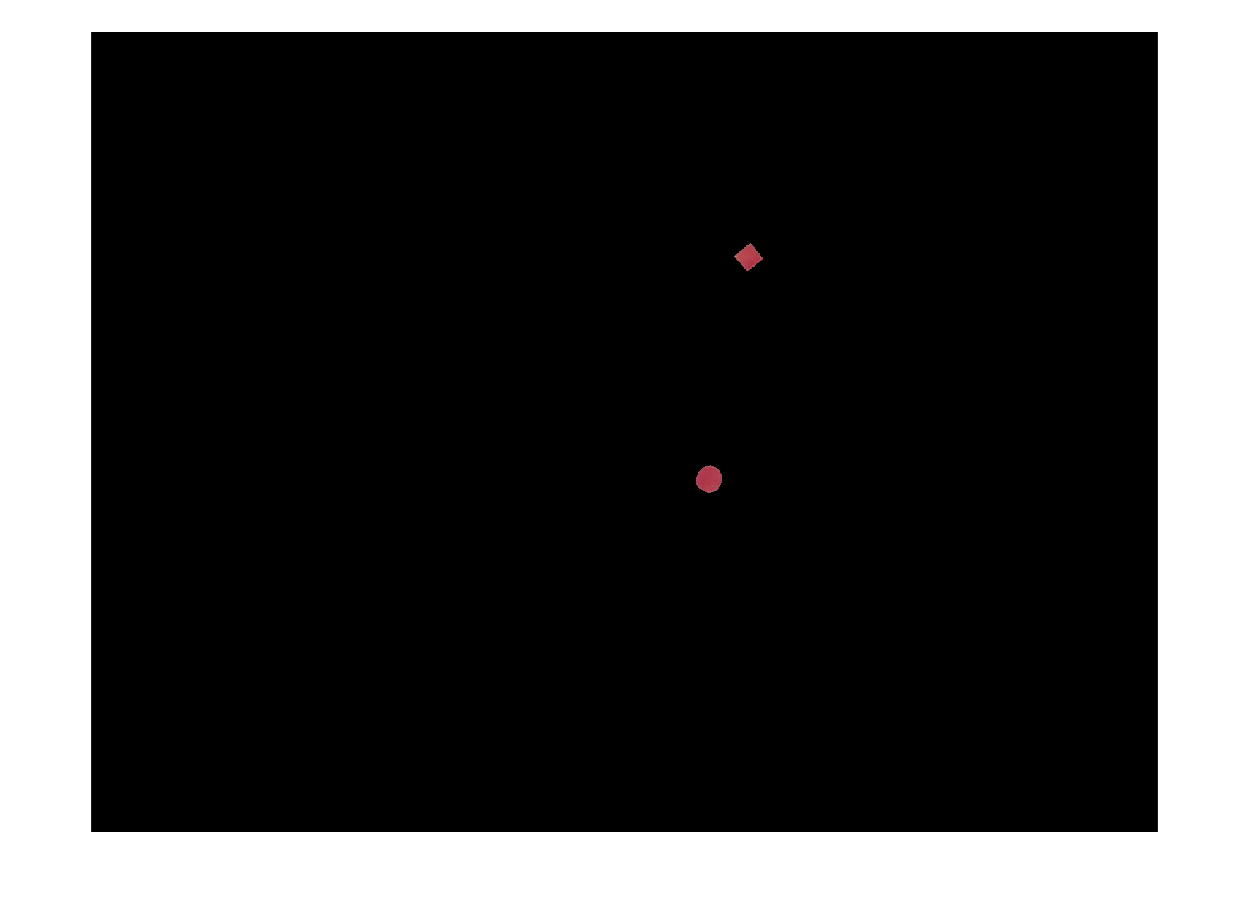


%{
patternProps.Colour = [];
patternProps.Shape = [];
patternProps.Centroid = [];
patternProps.Orientation = [];
%}

%% Filter all colours
% red
[myPatternRedBW,myPatternRed] = createPatternRedMask(table_Img);
myPatternRedBW = imfill(myPatternRedBW,'holes');
myPatternRedBW = bwareaopen(myPatternRedBW,100);


% green
% green's bit more sensitive 
[myPatternGreenBW,myPatternGreen] = createPatternGreenMask3(table_Img);
myPatternGreenBW = bwareaopen(myPatternGreenBW,200);


% Blue
table_Img = imsharpen(table_Img, 'Radius', 5, 'Amount', 1.5);
[myPatternBlueBW,myPatternBlue] = createPatternBlueMask(table_Img);
myPatternBlueBW = bwareaopen(myPatternBlueBW,200);


% Yellow
[myPatternYellowBW,myPatternYellow] = createPatternYellowMask(table_Img);
myPatternYellowBW = bwareaopen(myPatternYellowBW,350);


figure; imshow(myPatternRed);

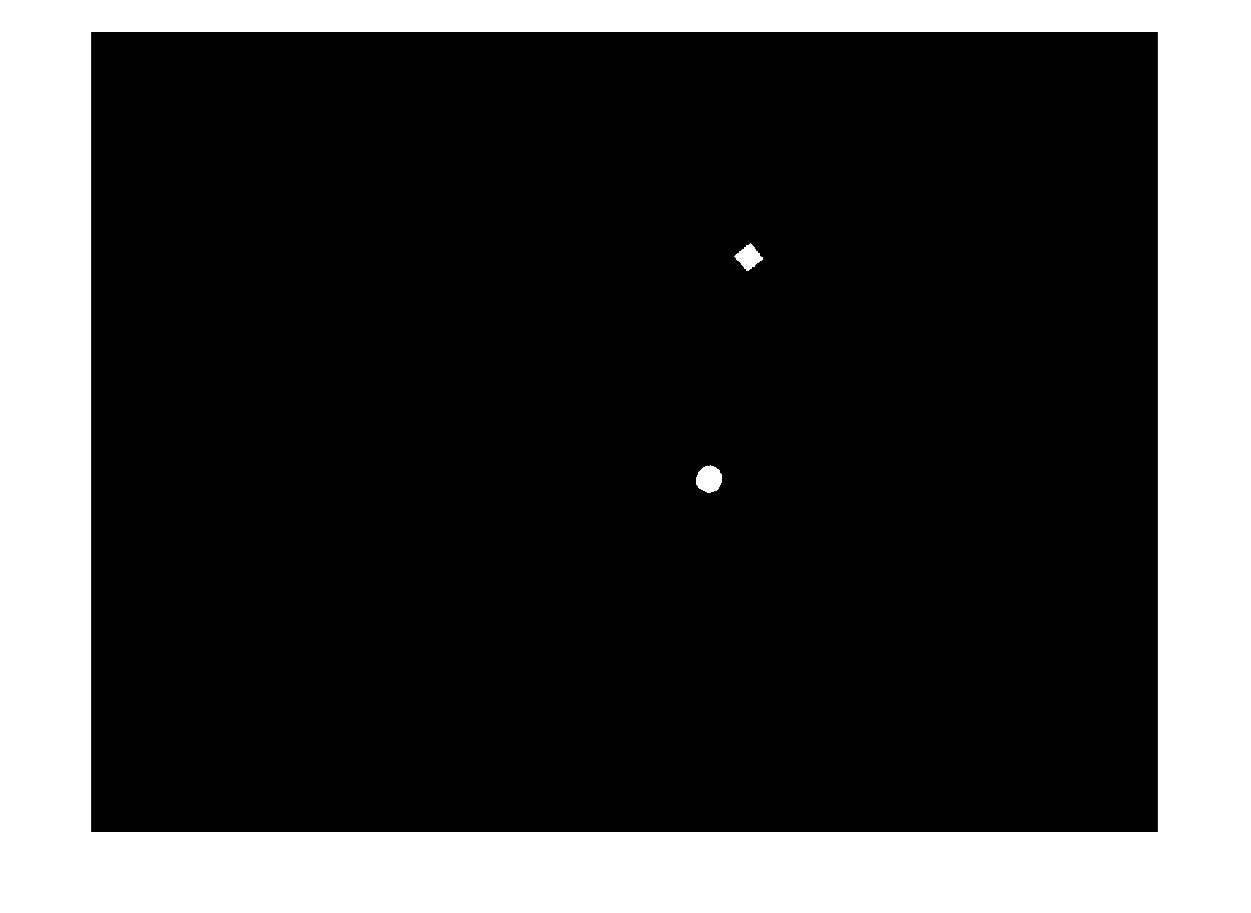

figure; imshow(myPatternRedBW);

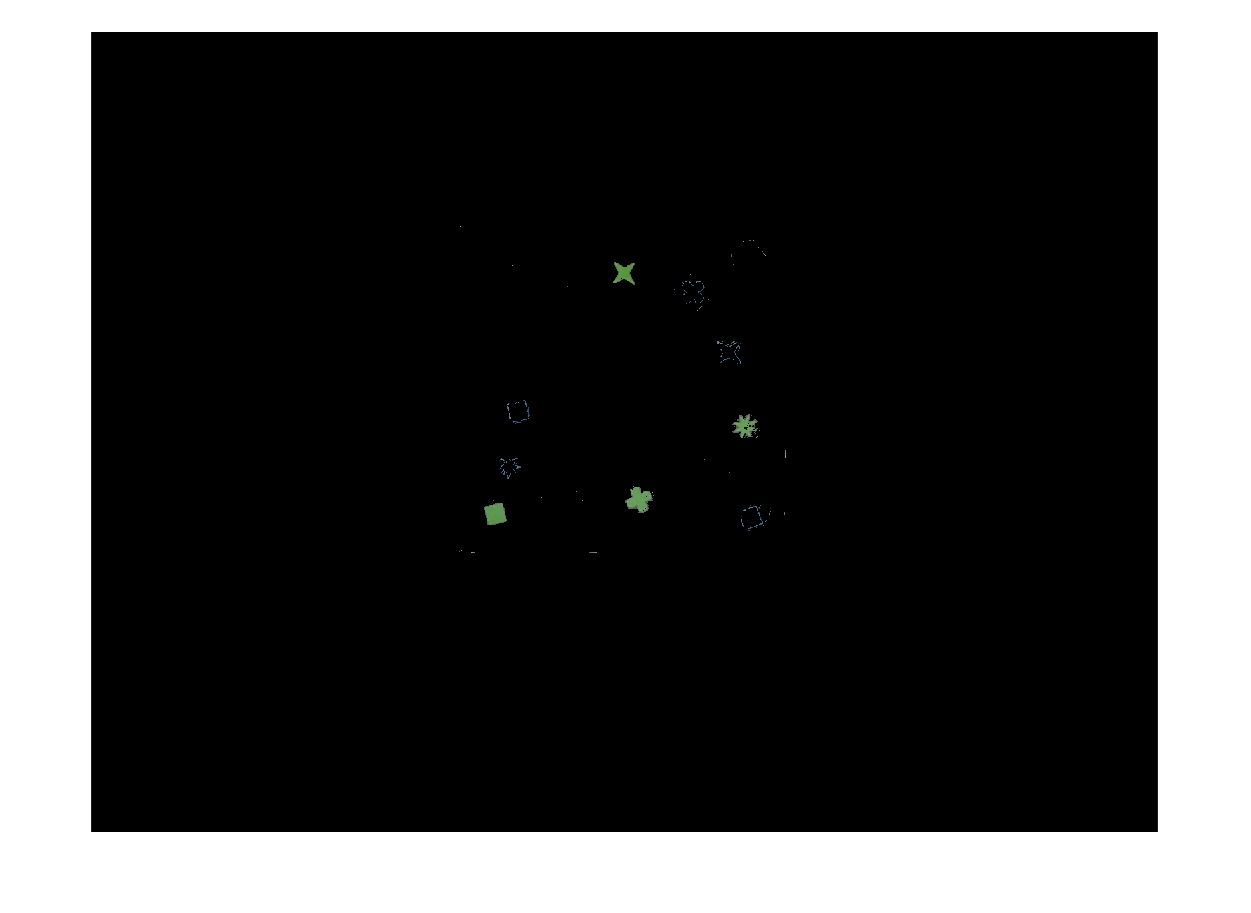

figure; imshow(myPatternGreen);

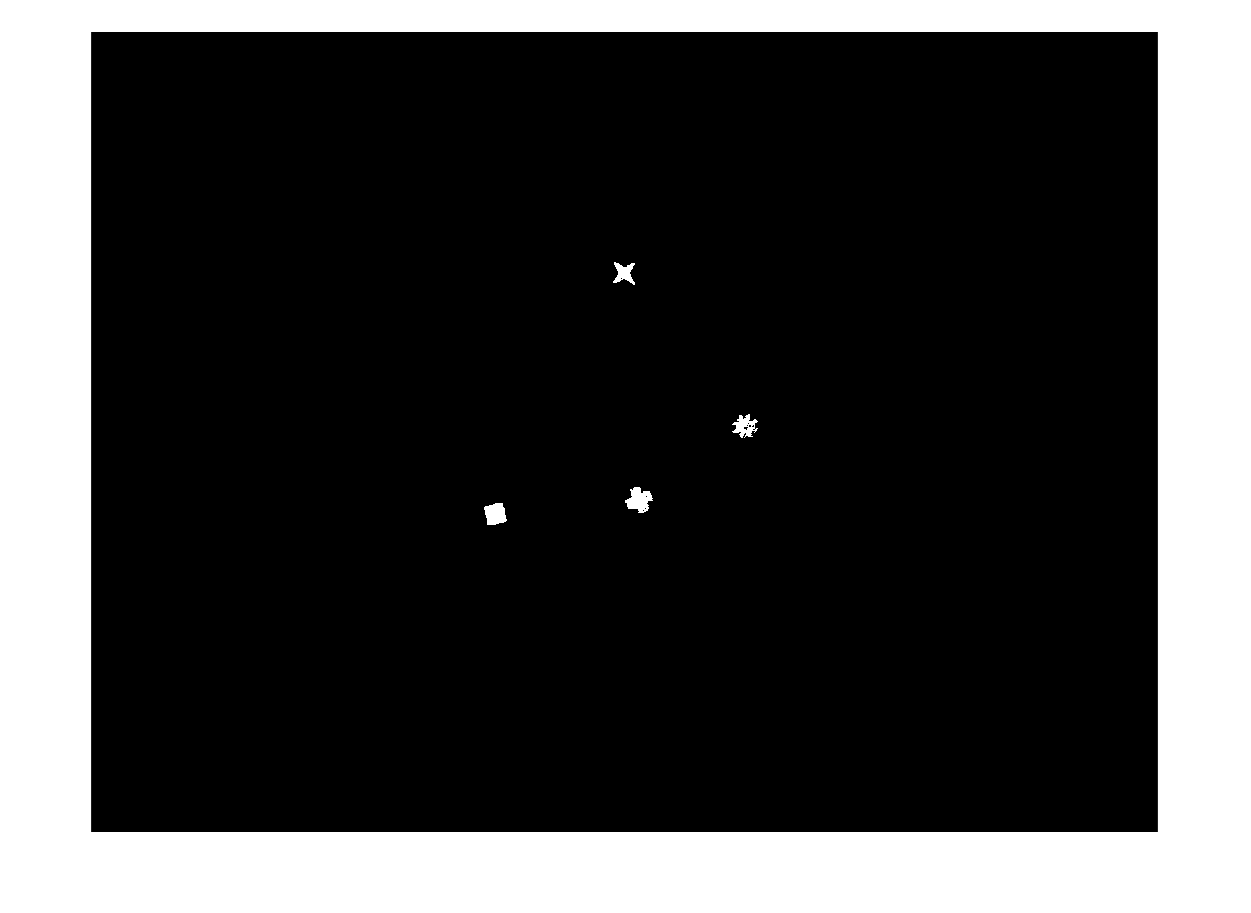

figure; imshow(myPatternGreenBW);

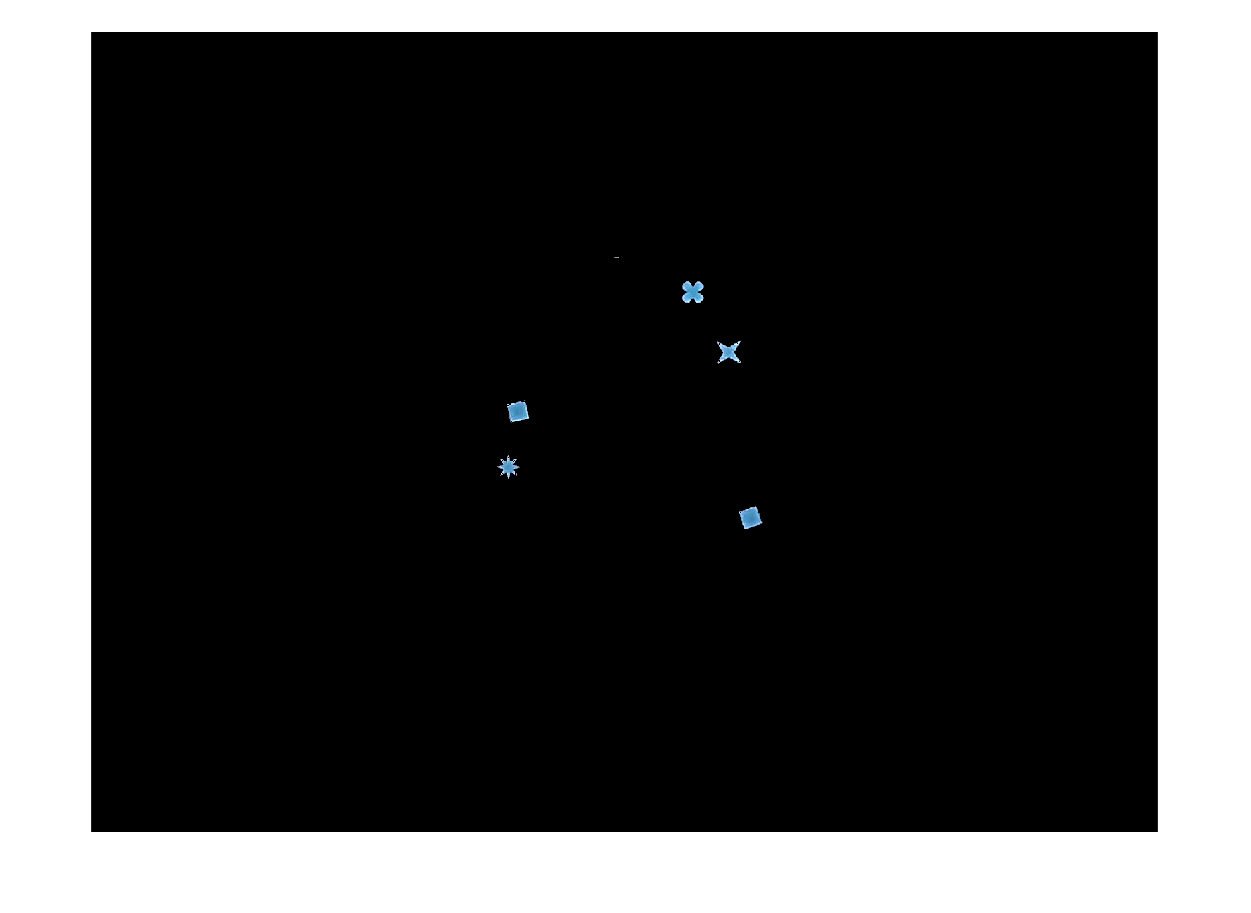

figure; imshow(myPatternBlue);

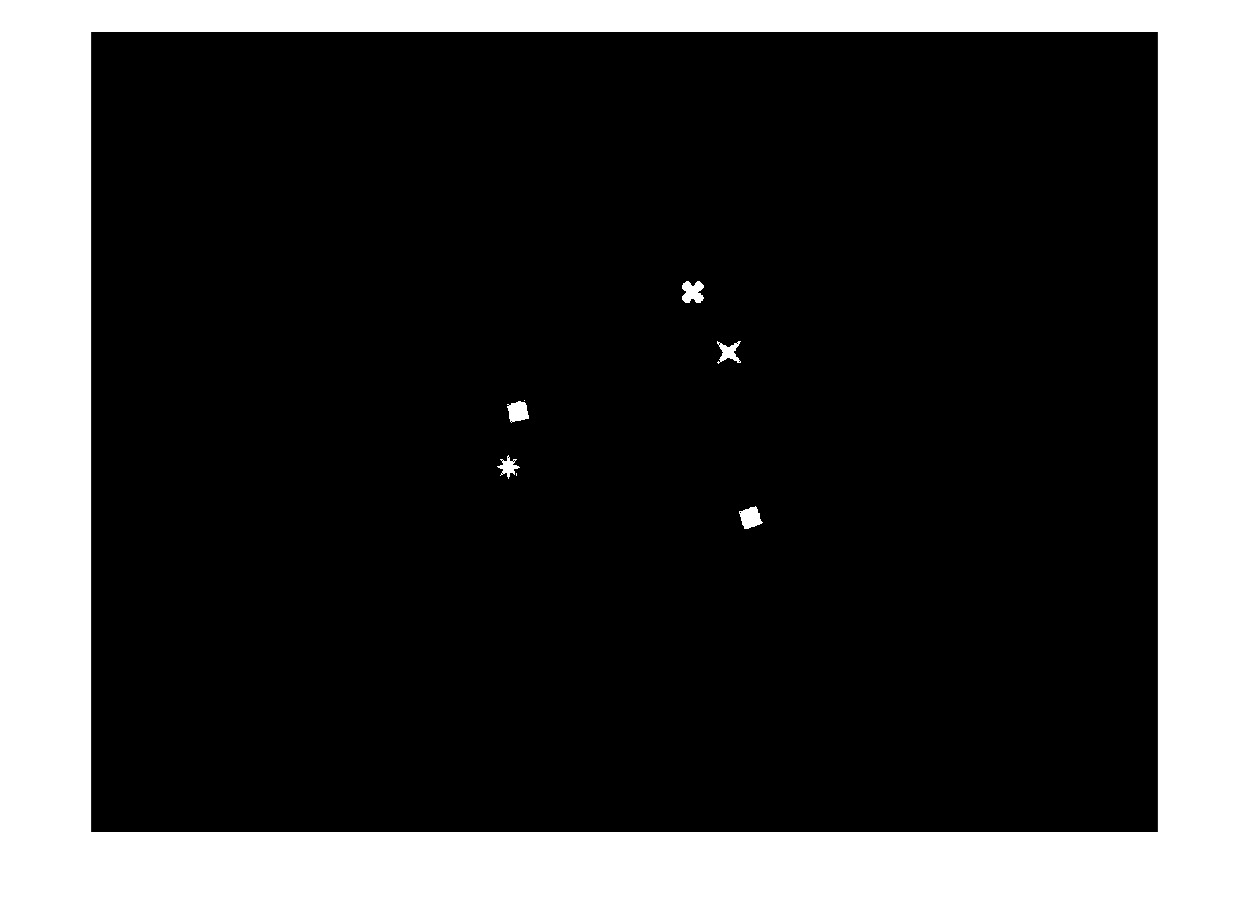

figure; imshow(myPatternBlueBW);

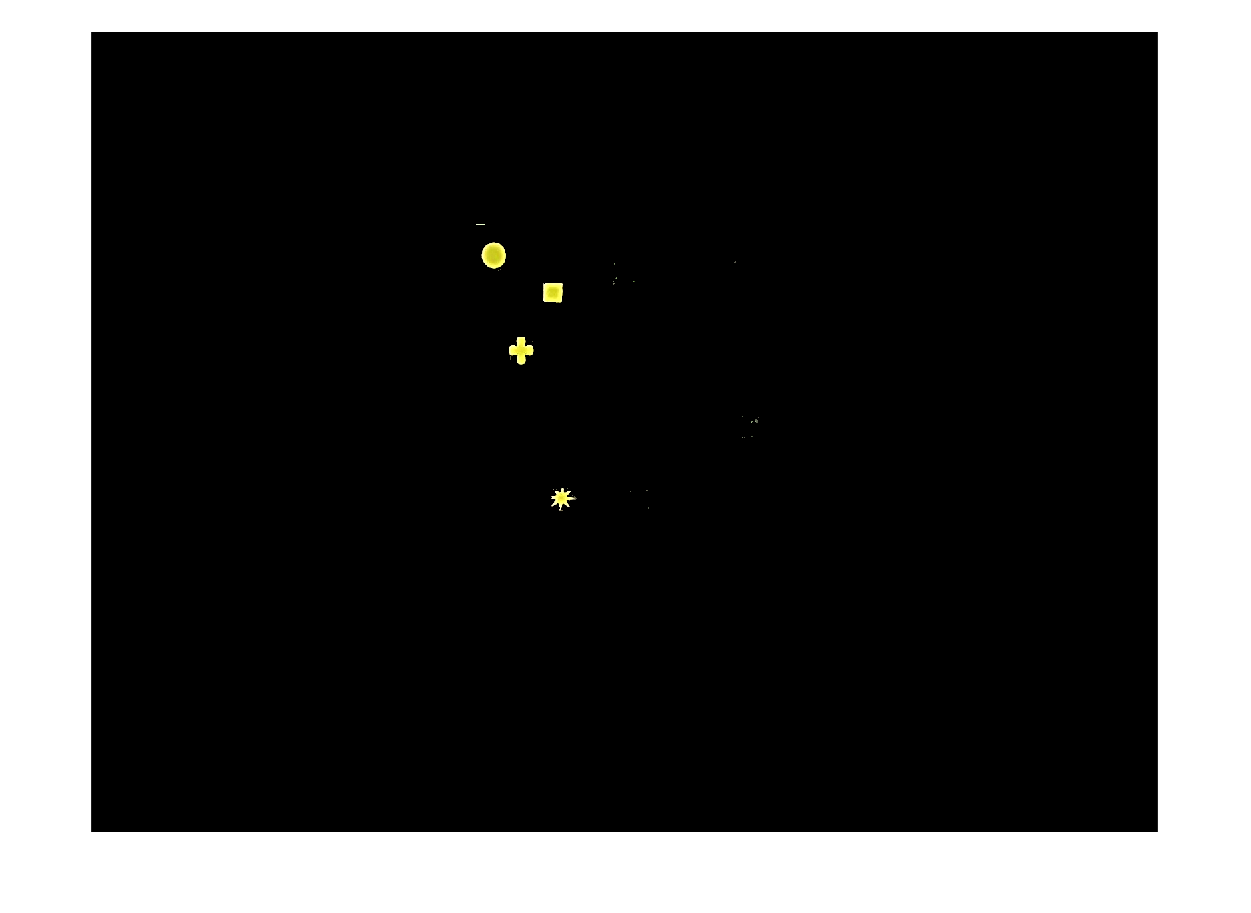

figure; imshow(myPatternYellow);

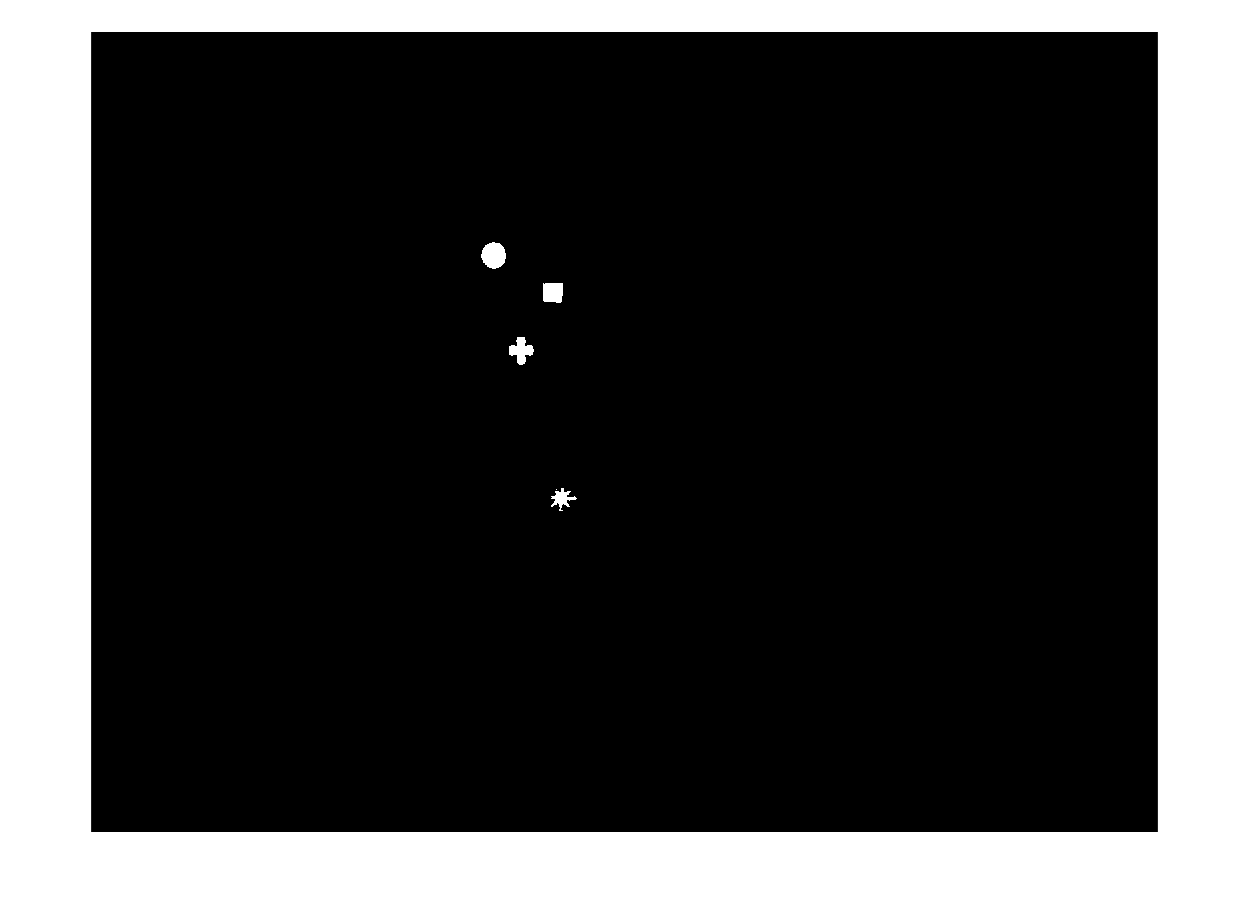

figure; imshow(myPatternYellowBW);

%}

%% See if the colours exists in the pattern
redExists = find(myPatternRedBW);
greenExists = find(myPatternGreenBW);
blueExists = find(myPatternBlueBW);
yellowExists = find(myPatternYellowBW);

% process red
if length(redExists) > 50 
    [redShape, redCentroid, redOrientation] = identifyAllRedShapes(myPatternRedBW, table_ImgBW);
    redCentroidWorld = tablePxlToReal(redCentroid(:,1), redCentroid(:,2));
else 
    display("No red exists in the pattern");
    redShape = [];
    redCentroid = [];
    redOrientation = [];
    redCentroidWorld = [];
end 

% process green
if length(greenExists) > 50 
    [greenShape, greenCentroid, greenOrientation] = identifyAllGreenShapes4(myPatternGreenBW, table_ImgBW);
    greenCentroidWorld = tablePxlToReal(greenCentroid(:,1), greenCentroid(:,2));
    
else
    display("No green exists in the pattern");
    greenShape = [];
    greenCentroid = [];
    greenOrientation = [];
    greenCentroidWorld = [];
end 

% process blue
if length(blueExists) > 50 
    [blueShape, blueCentroid, blueOrientation] = identifyAllBlueShapes2(myPatternBlueBW, table_ImgBW);
    blueCentroidWorld = tablePxlToReal(blueCentroid(:,1), blueCentroid(:,2));
    
else
    display("No blue exists in the pattern");
    blueShape = [];
    blueCentroid = [];
    blueOrientation = [];
    blueCentroidWorld = [];
end 

% process yellow
if length(yellowExists) > 50   
    [yellowShape, yellowCentroid, yellowOrientation] = identifyAllYellowShapes2(myPatternYellowBW, table_ImgBW);
    yellowCentroidWorld = tablePxlToReal(yellowCentroid(:,1), yellowCentroid(:,2));
else
    display("No yellow exists in the pattern");
    yellowShape = [];
    yellowCentroid = [];
    yellowOrientation = [];
    yellowCentroidWorld = [];
end

%{
patternProps.Colour = [ones(size(redShape, 1), 1)*red; ones(size(greenShape, 1), 1)*green;...
                        ones(size(blueShape, 1), 1)*blue; ones(size(yellowShape, 1), 1)*yellow];
patternProps.Shape = [redShape; greenShape; blueShape; yellowShape];
patternProps.Centroid = [redCentroidWorld; greenCentroidWorld; blueCentroidWorld; yellowCentroidWorld];
patternProps.Orientation = [redOrientation; greenOrientation; blueOrientation; yellowOrientation];
%}


patternProps = [ones(size(redShape, 1), 1)*red redShape redCentroid redOrientation;...
    ones(size(greenShape, 1), 1)*green greenShape greenCentroid greenOrientation;...
    ones(size(blueShape, 1), 1)*blue blueShape blueCentroid blueOrientation;...
    ones(size(yellowShape, 1), 1)*yellow yellowShape yellowCentroid yellowOrientation];
%}

%{
%% For testing puspose, copy to the command prompt after you run this code
patternProps = ans;
table_Img = imread('Proper_Pics\PrintedPics\sup.jpg');
figure; imshow(table_Img); hold on; 
for n = 1:size(patternProps,1)
    plot(patternProps(n,3), patternProps(n,4), 'c*', 'MarkerSize', 8);
    pause;
end
%}